% Create some plots
close all
clear
clc
warning ('off','all');

problem_name = 'short_term';
problem_type = 1;
var_level = 0;
train_data = load(['separated_train_data_',problem_name,'_',...
num2str(var_level),'_var.mat']); 
test_data = load(['test_data_',problem_name,'_',...
num2str(var_level),'_var.mat']).test_data;

train_data_table=[train_data.train_data_static;train_data.train_data_mobile];

train_data_cell={};
count=[];
num_static=[];
flag=0;
for i=2:size(train_data_table,1)
    if (train_data_table.time(i)< train_data_table.time(i-1))
       count=[count,i];
       if (i>size(train_data.train_data_static,1)&&(flag==0))
         num_static=length(count);
         flag=1;
       end
    end
end
count=[1,count,size(train_data_table,1)+1];

for i=2:length(count)
    train_data_cell{i-1}=train_data_table(count(i-1):count(i)-1,:);
end
num_static=num_static(1);
num_mobile=size(train_data_cell,2)-num_static;
data_combine=train_data_cell;%one cell with all data with tables for each sensor. 

fig = figure('Position', [0,0,900,400]);

for i=1:num_static %only static
    dat = data_combine{i};
    Y = fft(detrend(dat.pm2d5)); %Compute detrended fft
    L = height(dat); %Lengh of sample
    P2 = abs(Y/L); %Magnitude
    P1 = P2(1:L/2+1); %Single side spectrum
    if rem(height(dat),2)==0 %if even
        P1(2:end-1) = 2*P1(2:end-1); %Double amplitude
    else %if odd
        P1(2:end) = 2*P1(2:end);
    end

%plot
    Fs=1/3;%minute
    f = Fs*(0:(L/2))/L; %Frequency axis 0 to Nyquist freq

%     subplot(num_static,1,i)
    plot(f, P1)
    xlim([0,3e-5]);
    % Find location of first 3 maximum
    [temp,originalpos] = sort(P1, 'descend' );
    Max_amp = sort(temp(1:3),'descend');
    Max_pos = sort(originalpos(1:3),'descend');
    Max_freq = f(Max_pos);
    Max_period = 1./Max_freq./(24*3600) % In days
end

Max_period =     0.9965    1.4948    2.9896


Max_period =     0.7483    0.9978    1.4967


Max_period =     0.9970    1.4956    2.9911


Max_period =     0.9980    1.4970    2.9940


Max_period =     0.9963    1.4945    2.9890


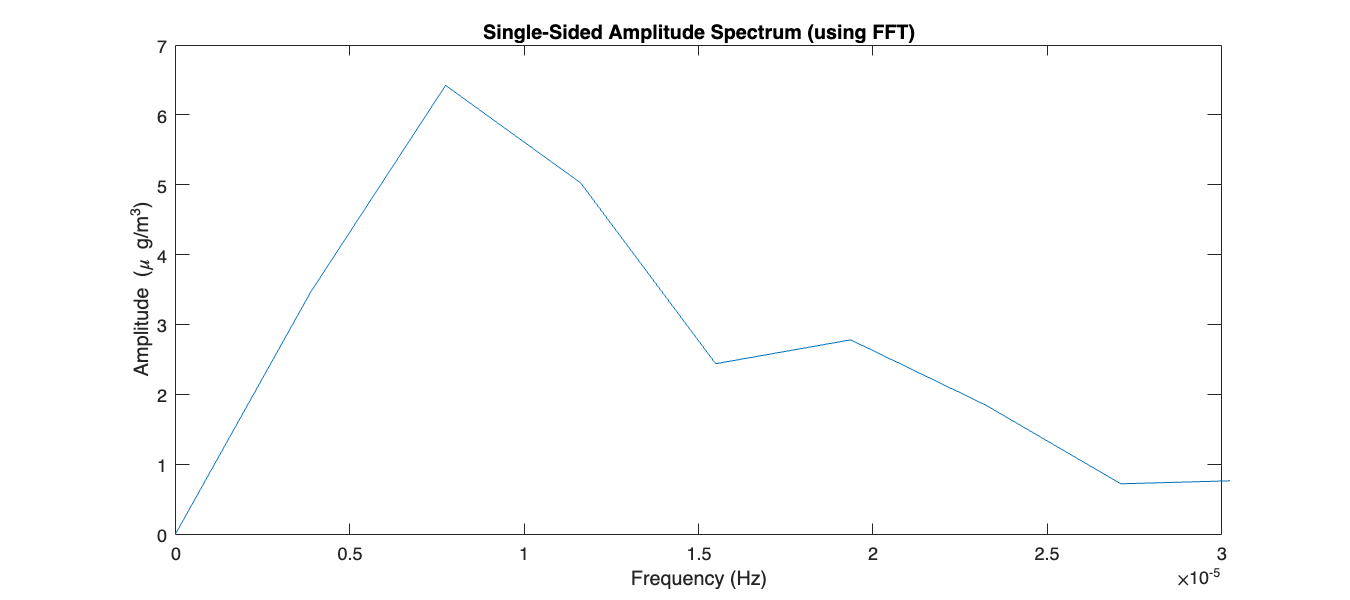

set(findall(gcf,'-property','FontSize'),'FontSize',12)
%label
% han=axes(fig,'Visible','off');
% han.Title.Visible = 'on';
% han.XLabel.Visible='on';
% han.YLabel.Visible='on';
% title(han,'Single-Sided Amplitude Spectrum (using FFT)')
title('Single-Sided Amplitude Spectrum (using FFT)')
xlabel('Frequency (Hz)')
ylabel('Amplitude (\mu g/m^3)')

fig = figure('Position', [0,0,900,400]);
%using the plomb to estimate the main frequency
for i=9
    dat = data_combine{i};
    y=dat.pm2d5;
    time=dat.time;
    time_num=datenum(time)*24*3600;
    y=detrend(y);
    [pxx,f] = plomb(y,time_num,5e-5);
%     subplot(num_mobile,1,i-5)
    plot(f,pxx)
    xlim([0,6e-5]);
    [temp,originalpos] = sort(pxx, 'descend' );
    Max_amp = sort(temp(1:3),'descend');
    Max_pos = sort(originalpos(1:3),'descend');
    Max_freq = f(Max_pos);
    Max_period = 1./Max_freq./(24*3600)
end 

Max_period =     0.7500
    0.9231
    1.7143


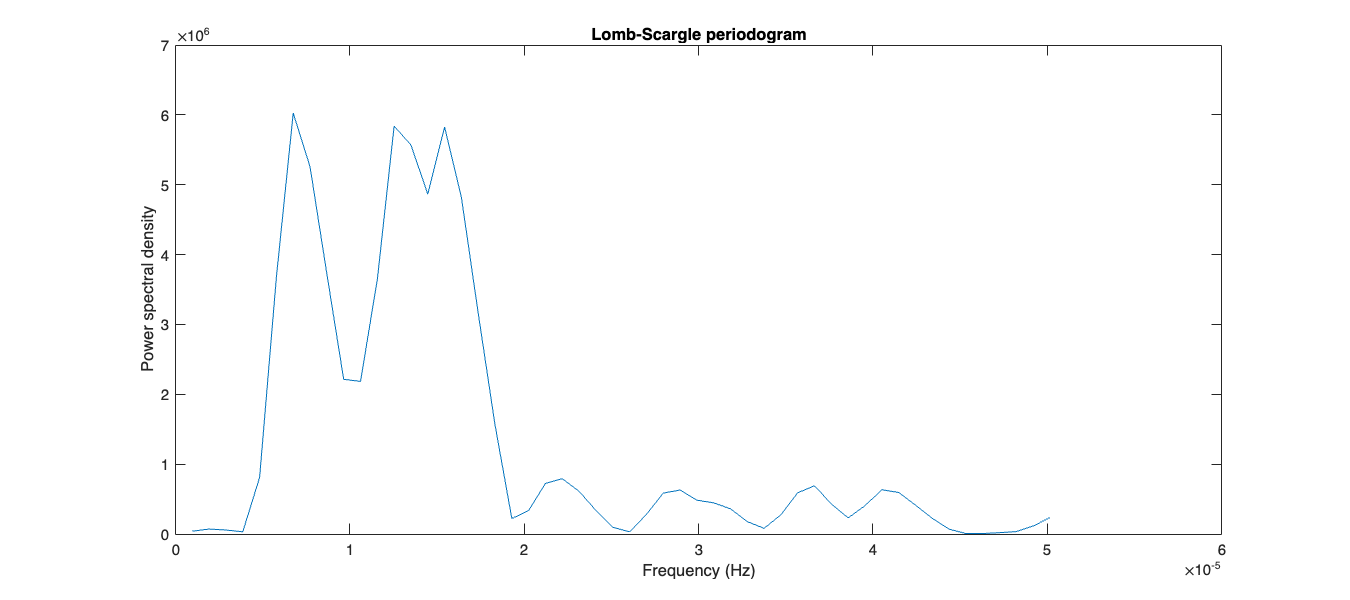

% set(findall(gcf,'-property','FontSize'),'FontSize',12)
%label
% han=axes(fig,'Visible','off');
% han.Title.Visible = 'on';
% han.XLabel.Visible='on';
% han.YLabel.Visible='on';
 title('Lomb-Scargle periodogram')
 xlabel('Frequency (Hz)')
 ylabel('Power spectral density')

%turning into minutely data
clearvars table
data_total_minute=cell(1,length(data_combine));
for i=1:length(data_combine)
    timearray=[];
    dataarray=[];
    time=data_combine{i}.time;
    %calculate the minute average data
    date = floor(datenum(time));
    unique_date = unique(date);
    date_ = datestr(time,'mm/dd/yyyy');
    date_ = gather(date_);
    [dayNumber,dayName] = weekday(datenum(date_,'mm/dd/yyyy'));
    hour_ = datestr(time,'HH');
    minute_=datestr(time,'MM');
    data = addvars(data_combine{i}, date_, dayName, hour_,minute_,dayNumber, 'Before','time',...
                    'NewVariableNames',{'date','dayName','hour','minute','dayNumber'});
    data_gb_datemin = grpstats(data,{'date','hour','minute'},{'mean'},'DataVars',{'hmd','spd','tmp','pm2d5','lat','lon'});
    
    time_minutely = unique(datetime(datenum(date_)+str2num(hour_)/24+str2num(minute_)/24/60,...
        'ConvertFrom','Datenum'));
    timearray=[timearray;time_minutely];
    dataarray=[dataarray;table2array(data_gb_datemin(:,5:10))];

data_total_minute{i}=[table(timearray),array2table(dataarray)];
data_total_minute{i}.Properties.VariableNames = ["time",'hmd','spd','tmp','pm2d5','lat','lon'];
end

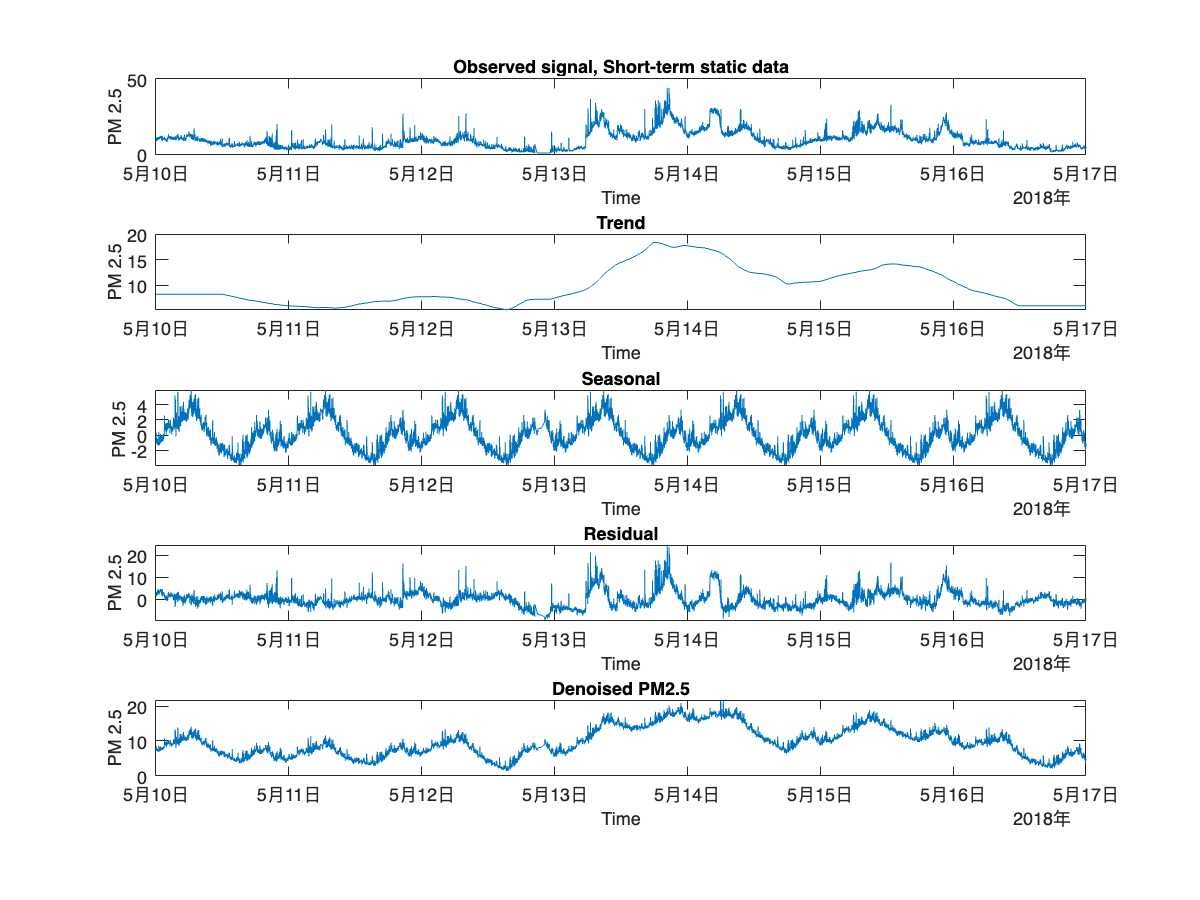

% %setting the period 
% if (problem_type==1)|(problem_type==3)
%     scale=1;
% else
%     scale =2;
% end
fig = figure('Position', [0,0,800,600]);

scale = 1;
scale_parameter=0.5;

%seasonal decomposition for static
data_cleaned_static=cell(1,num_static);
for i= 1: num_static %only static
    subplot(5,1,1)
    plot(data_total_minute{i}.time, data_total_minute{i}.pm2d5)
    title('Observed signal, Short-term static data')
    ylabel('PM 2.5')
    xlabel('Time')
    set(findall(gcf,'-property','FontSize'),'FontSize',12)


    T=60*24*scale;
    sw25=[1/(2*T);repmat(1/T,T-1,1);1/(2*T)];
    trend=conv(data_total_minute{i}.pm2d5,sw25,'same');
    %padding the trend
    trend_padded=[repmat(trend(T/2+1),T/2,1);trend(T/2+1:end-T/2);repmat(trend(end-T/2),T/2,1)];
    subplot(5,1,2)
    plot(data_total_minute{i}.time, trend_padded)
    title('Trend')
    ylabel('PM 2.5')
    xlabel('Time')
    set(findall(gcf,'-property','FontSize'),'FontSize',12)


    T1=length(data_total_minute{i}.pm2d5);
    sidx=cell(T,1);
    for ii=1:T
        sidx{ii,1}=ii:T:T1;
    end
    
    detrend_data=data_total_minute{i}.pm2d5-trend_padded;%detrend
    seasonal=cellfun(@(x) mean(detrend_data(x)),sidx); %generate seasonal trend
    nc=floor(T1/T);
    rm=mod(T1,T);
    seasonal=[repmat(seasonal,nc,1);seasonal(1:rm)];
    sBar=mean(seasonal);
    seasonal=seasonal-sBar;
    subplot(5,1,3)
    plot(data_total_minute{i}.time, seasonal)
    title('Seasonal')
    ylabel('PM 2.5 ')
    xlabel('Time')
    set(findall(gcf,'-property','FontSize'),'FontSize',12)

    residual=data_total_minute{i}.pm2d5-trend_padded-seasonal;
    
    subplot(5,1,4)
    plot(data_total_minute{i}.time, residual)
    title('Residual')
    ylabel('PM 2.5')
    xlabel('Time')
    set(findall(gcf,'-property','FontSize'),'FontSize',12)

    pm2d5_clean=trend_padded+seasonal;
    time=data_total_minute{i}.time;
    data_cleaned_static{i}=table(time,pm2d5_clean);
    subplot(5,1,5)
    plot(data_cleaned_static{i}.time,data_cleaned_static{i}.pm2d5_clean)
    title('Denoised PM2.5')
    ylabel('PM 2.5')
    xlabel('Time')
    set(findall(gcf,'-property','FontSize'),'FontSize',12)
end

%seasonal trend for mobile
data_cleaned_mobile=cell(1,num_mobile);
for i=num_static+1:length(data_total_minute) %only mobile
    T=60*24*scale;%1 days
    sw25=[1/(2*T);repmat(1/T,T-1,1);1/(2*T)];
    trend=conv(data_total_minute{i}.pm2d5,sw25,'same');
    %padding the trend
    trend_padded=[repmat(trend(T/2+1),T/2,1);trend(T/2+1:end-T/2);repmat(trend(end-T/2),T/2,1)];

    T1=length(data_total_minute{i}.pm2d5);
    sidx=cell(T,1);
    for ii=1:T
        sidx{ii,1}=ii:T:T1;
    end
    
    detrend_data=data_total_minute{i}.pm2d5-trend_padded;%detrend
    seasonal=cellfun(@(x) mean(detrend_data(x)),sidx); %generate seasonal trend
    nc=floor(T1/T);
    rm=mod(T1,T);
    seasonal=[repmat(seasonal,nc,1);seasonal(1:rm)];
    sBar=mean(seasonal);
    seasonal=seasonal-sBar;
    residual=data_total_minute{i}.pm2d5-trend_padded-seasonal;
    pm2d5_clean=trend_padded+seasonal;
    time=data_total_minute{i}.time;
    data_cleaned_mobile{i-num_static}=table(time,pm2d5_clean);
end

% data_total_pro_10 = data_total_minute{10};
% data_total_pro_10.pm2d5 = data_cleaned_mobile{4}.pm2d5_clean;


%parameter for static sensor
data_total_pro=data_total_minute;
for i=1:num_static
    data_total_pro{i}.pm2d5=data_cleaned_static{i}.pm2d5_clean;
    data_total_pro{i}.hmd= smoothdata(data_total_pro{i}.hmd,'Gaussian',60*24*scale_parameter);
    data_total_pro{i}.spd= smoothdata(data_total_pro{i}.spd,'Gaussian',60*24*scale_parameter);
    data_total_pro{i}.tmp= smoothdata(data_total_pro{i}.tmp,'Gaussian',60*24*scale_parameter);
end

%parameter for mobile sensor

for i=1:num_mobile
    data_total_pro{i+num_static}.pm2d5=data_cleaned_mobile{i}.pm2d5_clean;
    data_total_pro{i+num_static}.hmd= smoothdata(data_total_pro{i+num_static}.hmd,'Gaussian',60*24*0.25);
    data_total_pro{i+num_static}.spd= smoothdata(data_total_pro{i+num_static}.spd,'Gaussian',60*24*0.25);
    data_total_pro{i+num_static}.tmp= smoothdata(data_total_pro{i+num_static}.tmp,'Gaussian',60*24*0.25);
end

clearvars table
data_onematrix=table;
for i=1:length(data_total_pro)
    data_onematrix=[data_onematrix;data_total_pro{i}];
end
data_total_sorted= sortrows(data_onematrix);


%normalize the data, range
timenum_train=datenum(data_total_sorted.time);
test_data.time=datenum(test_data.time);
data_total_norm_para=[timenum_train,data_total_sorted.hmd,data_total_sorted.spd,...
    data_total_sorted.tmp,data_total_sorted.lat,data_total_sorted.lon];
% data_total_norm_para_withtest=[data_total_norm_para;table2array(test_data)];
data_total_norm_para=normalize(data_total_norm_para,'range');
y = data_total_sorted.pm2d5;
total = [data_total_norm_para,y]

total =          0    0.1107    0.0020    0.4572    0.0729    0.0000   45.8025
         0    0.1843    0.0009    0.4755    0.1383    0.2834    7.3026
         0    0.1857    0.0043    0.4343    0.5114    0.2127   42.3187
         0    0.2818    0.0043    0.3938    0.6592    0.4520   46.1007
         0    0.2942    0.0022    0.3875    0.6592    0.4520   50.5334
         0    0.3028    0.0058    0.3428    0.6592    0.4520   42.7013
    0.0001    0.1107    0.0020    0.4571    0.0729    0.0000   45.6576
    0.0001    0.1843    0.0009    0.4754    0.1383    0.2834    7.2671
    0.0001    0.1856    0.0043    0.4343    0.5114    0.2127   41.9097
    0.0001    0.2817    0.0043    0.3938    0.6592    0.4520   46.8382


% x=data_total_norm_para(1:33000,:);
% y = data_total_sorted.pm2d5(1:33000);
% gprMdl=fitrgp(x,y,'KernelFunction','matern32');
% pred_pm2d5=predict(gprMdl,data_total_norm_para(33001:end,:));
% cvMdl = fitrtree(data_total_norm_para,data_total_sorted.pm2d5,'MinLeafSize', 4, 'Surrogate','off',KFold=5);
gprMdl=fitrgp(x,y,'KernelFunction','exponential');
% 
% y = data_total_sorted.pm2d5;
% 
% gprMdl=fitrgp(x,y,'KernelFunction','matern32');
% pred_pm2d5=predict(gprMdl,data_total_norm_para_withtest(end-size(test_data,1)+1:end,:));

kfoldLoss(cvMdl)

ans = 10.7527

xtest = table2array(test_data);
ypred = kfoldPredict(cvMdl)

ypred =    42.5471
   40.0490
   42.7305
   42.7206
   41.4336
   45.1153
   36.9033
   38.8969
   45.2437
   38.3997


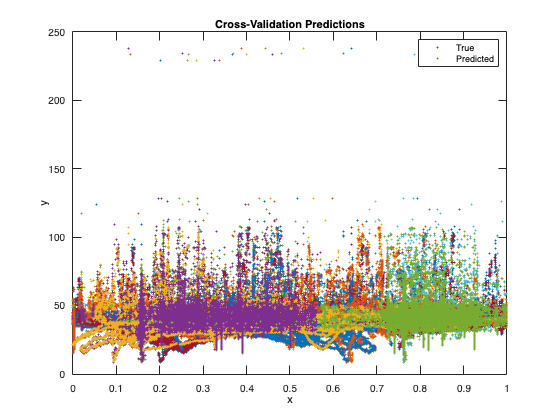

plot(data_total_norm_para,data_total_sorted.pm2d5,".");
hold on
plot(data_total_norm_para,ypred,".");
xlabel("x")
ylabel("y")
title("Cross-Validation Predictions")
legend(["True","Predicted"])
hold off